# Analysis of FFT Data

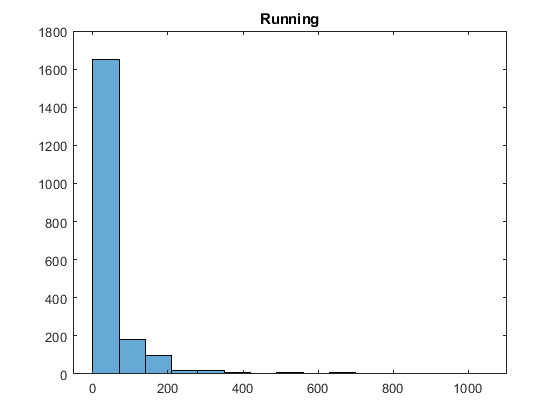

histogram(abs(runningAfft(:, 2:4)), 15)
title("Running")

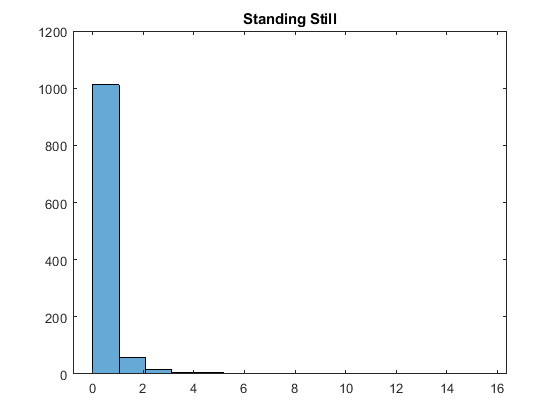

histogram(abs(stillAfft(:,2:4)), 15)
title("Standing Still")

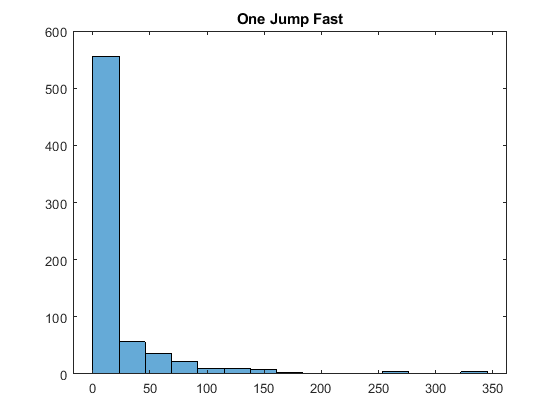

histogram(abs(oneJumpAfft(:, 2:4)), 15)
title("One Jump Fast")

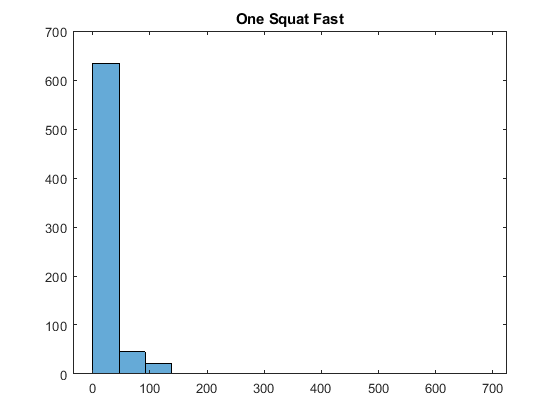

histogram(abs(oneSquatAfft(:, 2:4)), 15)
title("One Squat Fast")

#### Standing Still RMS Values

xStillrms = rms(stillAfft(:, 2))

xStillrms = 0.7337

yStillrms = rms(stillAfft(:, 3))

yStillrms = 0.4976

zStillrms = rms(stillAfft(:, 4))

zStillrms = 1.3494

#### Running RMS Values

xRunningrms = rms(runningAfft(:, 2))

xRunningrms = 81.4854

yRunningrms = rms(runningAfft(:, 3))

yRunningrms = 136.0007

zRunningrms = rms(runningAfft(:, 4))

zRunningrms = 79.0866

#### Jumping RMS Values

xJumpingrms = rms(oneJumpAfft(:, 2))

xJumpingrms = 20.1991

yJumpingrms = rms(oneJumpAfft(:, 3))

yJumpingrms = 72.7006

zJumpingrms = rms(oneJumpAfft(:, 4))

zJumpingrms = 32.0527

#### Squatting RMS Values

xSquattingrms = rms(oneSquatAfft(:, 2))

xSquattingrms = 27.4110

ySquattingrms = rms(oneSquatAfft(:, 3))

ySquattingrms = 38.4952

zSquattingrms = rms(oneSquatAfft(:, 4))

zSquattingrms = 58.8456

## Plotting RMS Values on Same Graph

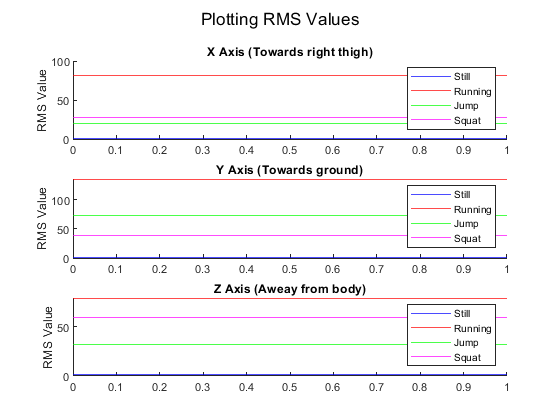

figure()
sgtitle("Plotting RMS Values")
subplot(3,1,1)
hold on;
yline(xStillrms, "b")
yline(xRunningrms, "r")
yline(xJumpingrms, "g")
yline(xSquattingrms, "m")
legend("Still", "Running", "Jump", "Squat")
ylabel("RMS Value")
title("X Axis (Towards right thigh)")
hold off

subplot(3,1,2)
hold on;
yline(yStillrms, "b")
yline(yRunningrms, "r")
yline(yJumpingrms, "g")
yline(ySquattingrms, "m")
legend("Still", "Running", "Jump", "Squat")
ylabel("RMS Value")
title("Y Axis (Towards ground)")
hold off

subplot(3,1,3)
hold on;
yline(zStillrms, "b")
yline(zRunningrms, "r")
yline(zJumpingrms, "g")
yline(zSquattingrms, "m")
legend("Still", "Running", "Jump", "Squat")
ylabel("RMS Value")
title("Z Axis (Aweay from body)")
hold off

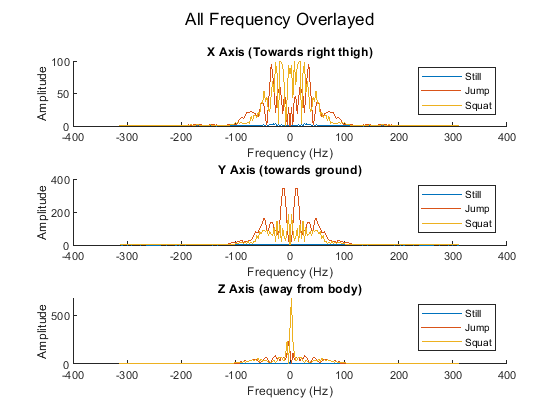

clf
figure()
sgtitle('All Frequency Overlayed')
hold on
subplot(3,1,1)
hold on
plot(stillAfft(:, 1), abs(stillAfft(:, 2)))
%plot(runningAfft(:, 1), abs(runningAfft(:, 2)))
plot(oneJumpAfft(:, 1), abs(oneJumpAfft(:, 2)))
plot(oneSquatAfft(:, 1), abs(oneSquatAfft(:, 2)))
legend("Still", "Jump", "Squat")

%legend('Good')%, 'Bad')
title('X Axis (Towards right thigh)')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off
subplot(3,1,2)
hold on
plot(stillAfft(:, 1), abs(stillAfft(:, 3)))
%plot(runningAfft(:, 1), abs(runningAfft(:, 2)))
plot(oneJumpAfft(:, 1), abs(oneJumpAfft(:, 3)))
plot(oneSquatAfft(:, 1), abs(oneSquatAfft(:, 3)))
legend("Still", "Jump", "Squat")
title('Y Axis (towards ground)')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off
subplot(3,1,3)
hold on
plot(stillAfft(:, 1), abs(stillAfft(:, 4)))
%plot(runningAfft(:, 1), abs(runningAfft(:, 2)))
plot(oneJumpAfft(:, 1), abs(oneJumpAfft(:, 4)))
plot(oneSquatAfft(:, 1), abs(oneSquatAfft(:, 4)))
legend("Still", "Jump", "Squat")
title('Z Axis (away from body)')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off

## Other values we could use to classify

Max in Z to classify squat?

squatZMax = max(abs(oneSquatAfft(:, 4)))

squatZMax = 677.8894

## Thinking About Threshold Values

If all <10 --> STANDING STILLl (Running = False)

Else RUNNING = True. NOTE this is a big gap, since running everything is over 50, and it wasn't a super vigorous run. What do we want to do?

If Y RMS is below 90 - CHECK for action

If Y RMS is between 15 & 45? &&  --> SQUAT

if Y RMS between 60-95 --> JUMP

Y in Jumping has way more variance than Y Squatting (to mulitple powers difference) but very close to running so not super helpful